# 3-D  Trajectory planning in task space passes through at least four via points

## Construct The Robot

clc; clear;
robot = importrobot('Franka_Emika_Panda.urdf');

robot.DataFormat = 'column';

Show details of the robot to validate the input properties. The robot should have two non-fixed joints, where the link bodies are connected to their parent bodies via a revolute joint, and the end effector is connected to its parent body via a fixed joint.


panda_model()
M;
B;
S;

The velocity profile has four parameters:

- **End Time **— Duration of each segment between two waypoints

- **Peak Velocity **— Peak velocity for a each segment

- **Acceleration Time** — Time spent in the acceleration and deceleration phases of each segment

- **Peak Acceleration **— Magnitude of the acceleration applied during the acceleration and deceleration phases of each segment

peakVelocities = [150, 150, 150, 150, 180, 180, 180]'.*pi/180;
vpa(peakVelocities', 5)

$$ans = \left(\begin{array}{ccccccc} 2.618 & 2.618 & 2.618 & 2.618 & 3.1416 & 3.1416 & 3.1416 \end{array}\right)$$

peakAcceleration = [850, 425, 570, 700, 850, 1140, 1140]'.*pi/180;
vpa(peakAcceleration', 5)

$$ans = \left(\begin{array}{ccccccc} 14.835 & 7.4176 & 9.9484 & 12.217 & 14.835 & 19.897 & 19.897 \end{array}\right)$$

### **Task-Space Trajectories**

A *task-space trajectory* contains waypoints that represent end-effector motion in 3-D space. Generate a cubic polynomial trajectory to connect waypoints in free space. The purpose of this trajectory profile is to create a smooth trajectory.Then generate the joint configurations of the Franka Emika Panda robot using inverse kinematics.

### Four arbitrary via points

frankaSpaceWaypoints = [0.5 0.25 0.35; 0.75 0 0.35; 0.6 -0.2 0.35; 0.5 -0.5 0.35]';
vpa(frankaSpaceWaypoints, 4)

$$ans = \left(\begin{array}{cccc} 0.5 & 0.75 & 0.6 & 0.5\\ 0.25 & 0 & -0.2 & -0.5\\ 0.35 & 0.35 & 0.35 & 0.35 \end{array}\right)$$

## Compare Various Trajectory Profiles

Gemerate trajectories using different tools, and then compare them using both task- and joint-space visualization.

wpts = frankaSpaceWaypoints;
tpts = 0:(size(wpts,2)-1);
% Derived quantities.
sampleRate = 20;
tvec = tpts(1):1/sampleRate:tpts(end);
numSamples = length(tvec)

numSamples = 61

t0 = 0; %Start Time
tf = 1; %Final Time
t = linspace(t0, tf, numSamples); % Time

dt = (tf-t0)/numSamples

dt = 0.0164

### Cubic Polynomial Trajectories

In the default case, these functions use zero-valued boundary conditions, resulting in trajectories that stop at every waypoint.

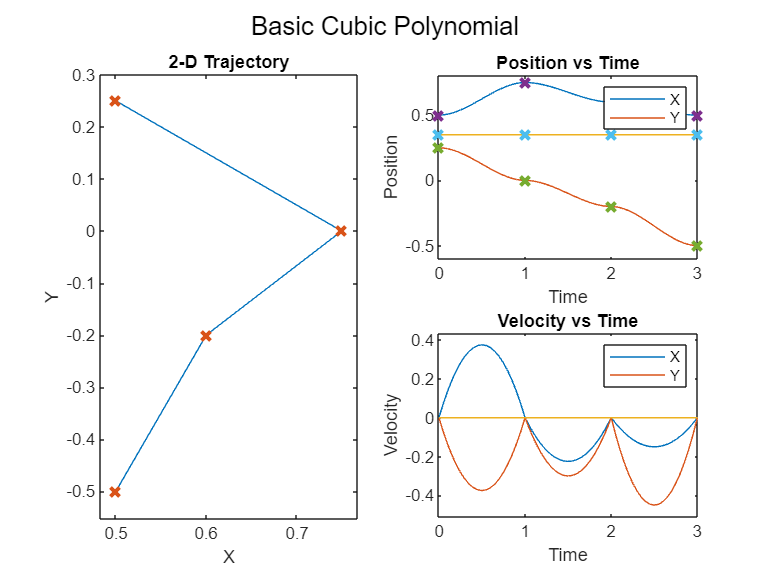

[pos,vel] = cubicpolytraj(wpts,tpts,tvec);
helperPlotTaskSpaceTraj('Basic Cubic Polynomial',tvec,pos,vel,wpts,tpts);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.

It is worth to note that the orientation of the end-effector frame is fixed during this motion.

q = zeros(7,numSamples);
initialGuess = [0.75, 0.13, -0.30, -2.1, 0.05, 2.25, 0.42]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;
    q(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end


Show the results using the robot model.

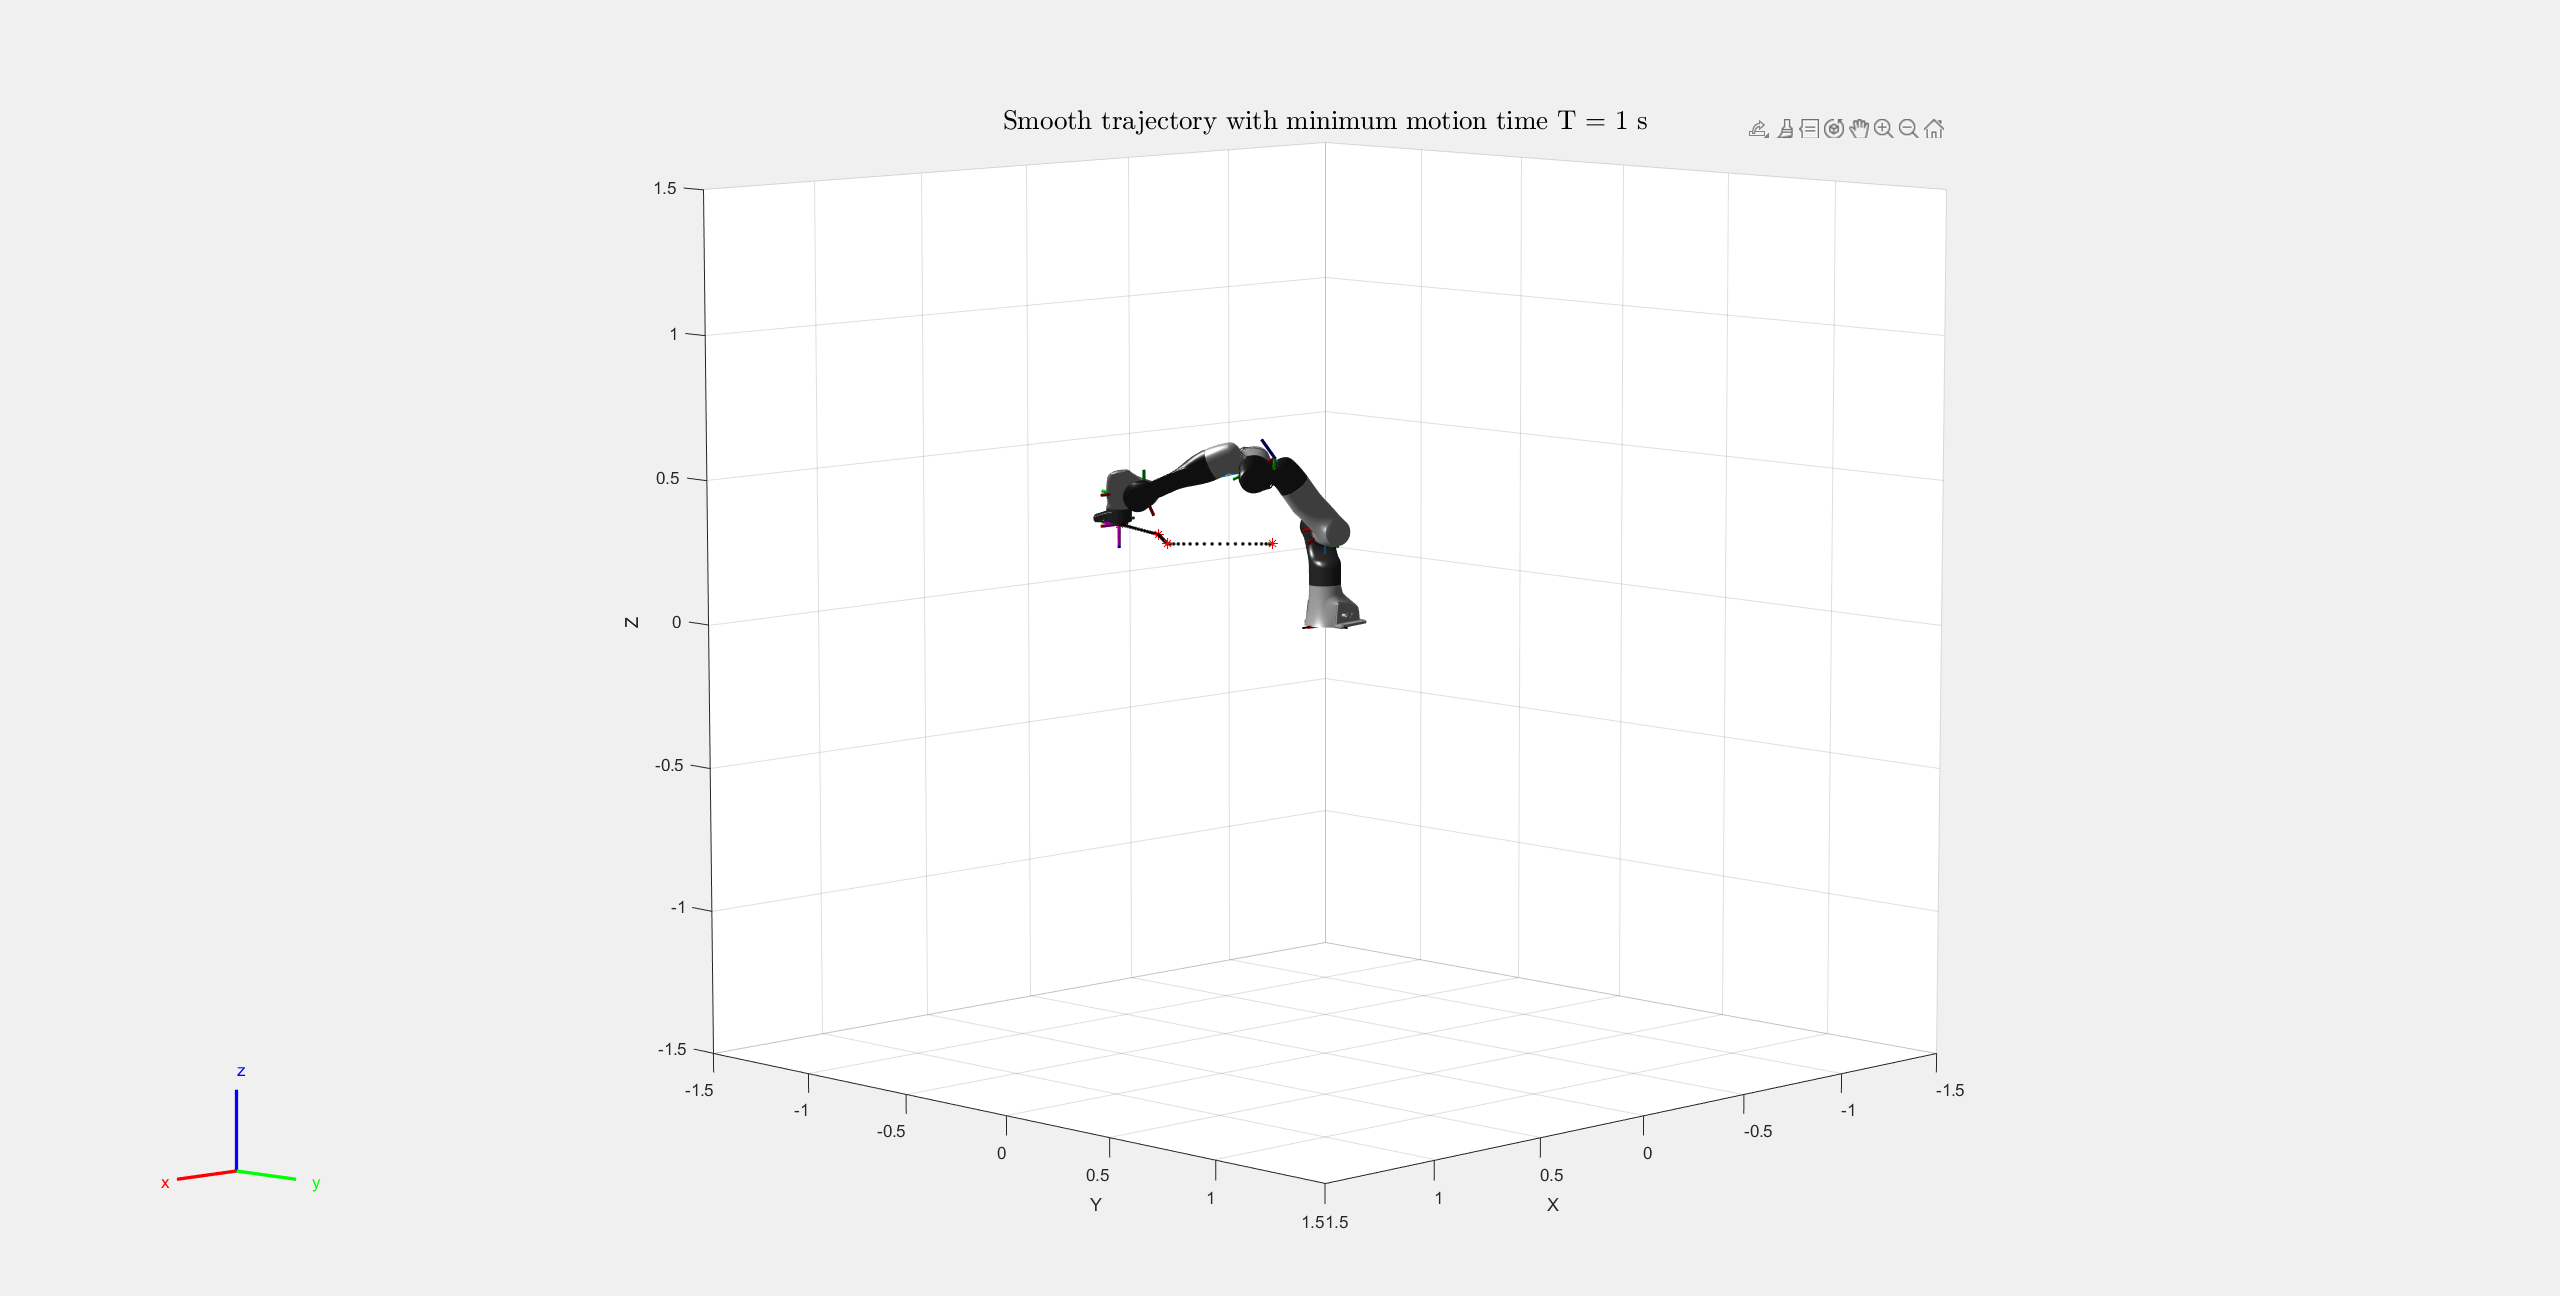

figure;
set(gcf,'Visible','on')
show(robot,q(:, 1), 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");

for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = trajs{i};

    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

vpa(trajs{1}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.5\\ 0 & -1.0 & -1.225e-16 & 0.25\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{20}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.7482\\ 0 & -1.0 & -1.225e-16 & 0.001812\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{40}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.6011\\ 0 & -1.0 & -1.225e-16 & -0.1986\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{60}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.5007\\ 0 & -1.0 & -1.225e-16 & -0.4978\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

**It is obvious that the orientation of the end-effecto is fixed.**

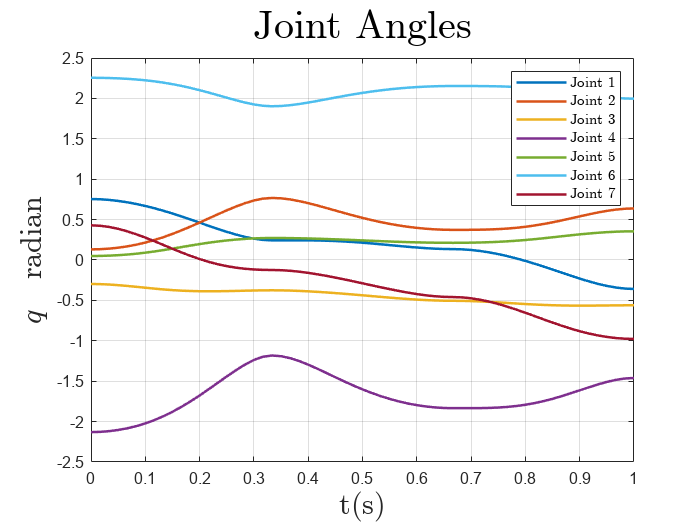


figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

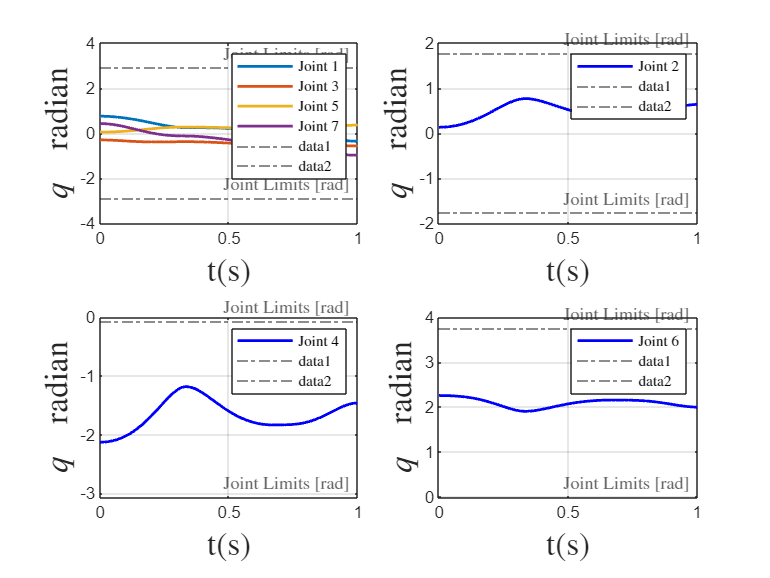

figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

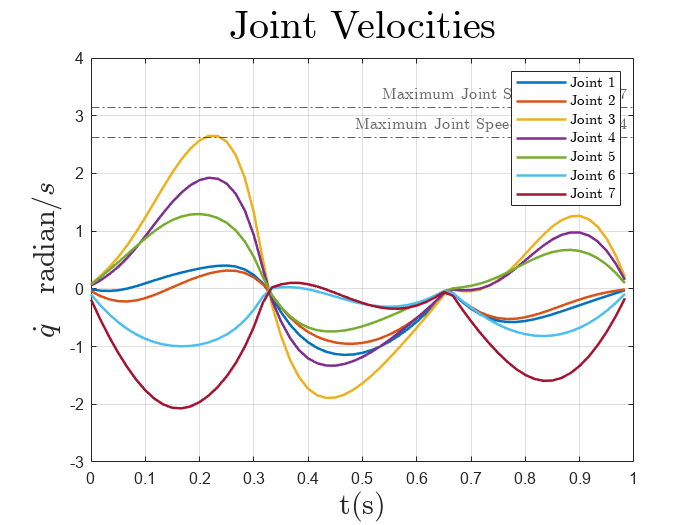


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

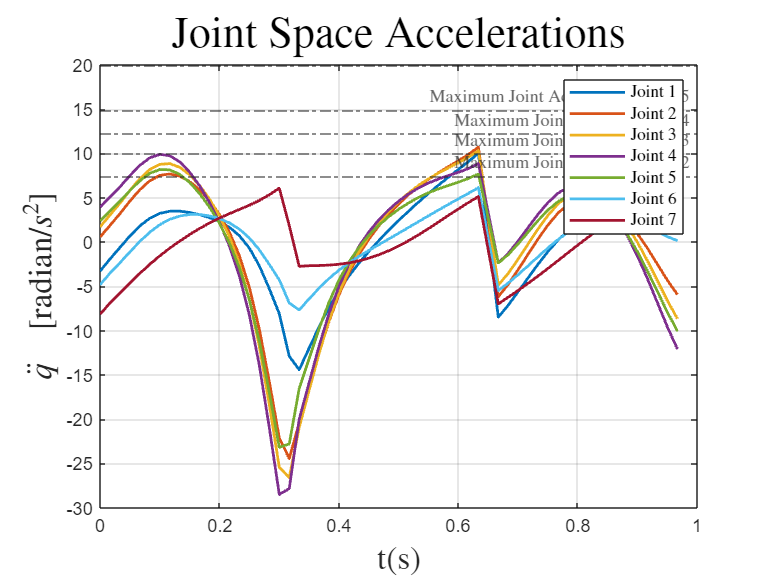


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

We can use this functions to design an interpolating polynomial with custom boundary behavior. For example, by using this functions with other piecewise polynomial tools like [`spline`](docid:matlab_ref#bvjdpi3), [`pchip`](docid:matlab_ref#bvjbxbd), or [`makima`](docid:matlab_ref#mw_fda58e3c-de78-4b86-beb0-98bd56d7d7b4), we can create smooth profiles with desirable motion at the waypoints.

This example code derives boundary conditions from one of the built-in piecewise polynomial functions in MATLAB. Select a polynomial function to see how it affects the cubic polynomial velocity profile. The code uses a helper file to compute the velocity.

smoothPP = spline(tpts,wpts);
smoothVelPP = mkpp(smoothPP.breaks,robotics.core.internal.polyCoeffsDerivative(smoothPP.coefs),size(wpts,1));
smoothVelPoly = ppval(smoothVelPP,tpts);


Use the derived velocity as the boundary condition for the inner waypoints. Leave the outside boundary conditions as zero velocity to ensure the trajectory starts and ends at zero velocity

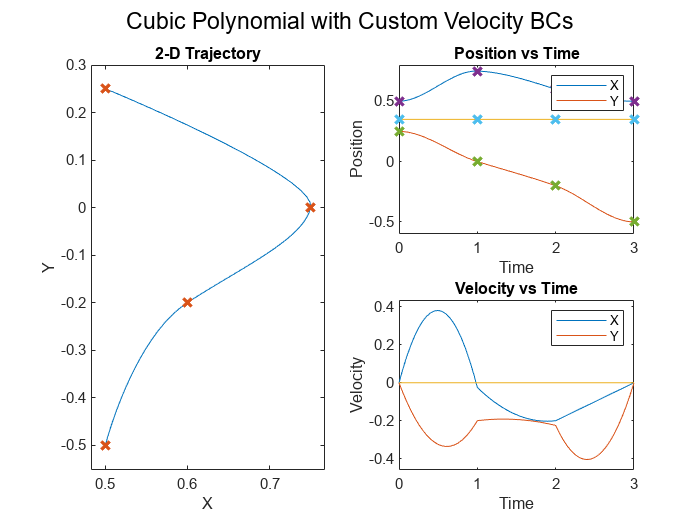

boundaryVel = zeros(size(smoothVelPoly));
boundaryVel(:,2:end-1) = smoothVelPoly(:,2:end-1);
[pos,vel] = cubicpolytraj(wpts,tpts,tvec,VelocityBoundaryCondition=boundaryVel);
helperPlotTaskSpaceTraj('Cubic Polynomial with Custom Velocity BCs',tvec,pos,vel,wpts,tpts);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.


q = zeros(7,numSamples);

initialGuess = [0.75, 0.13, -0.30, -2.1, 0.05, 2.25, 0.42]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;
    q(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end

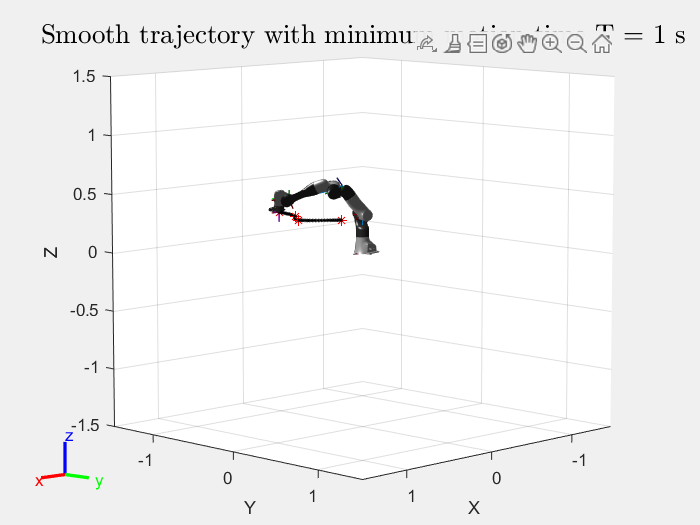

figure;
set(gcf,'Visible','on')
show(robot, q(:, 1), 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result1 = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = trajs{i};

    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

vpa(trajs{1}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.5\\ 0 & -1.0 & -1.225e-16 & 0.25\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{20}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.7493\\ 0 & -1.0 & -1.225e-16 & 0.01084\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{40}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.6101\\ 0 & -1.0 & -1.225e-16 & -0.1889\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(trajs{60}, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.5002\\ 0 & -1.0 & -1.225e-16 & -0.4984\\ 0 & 1.225e-16 & -1.0 & 0.35\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

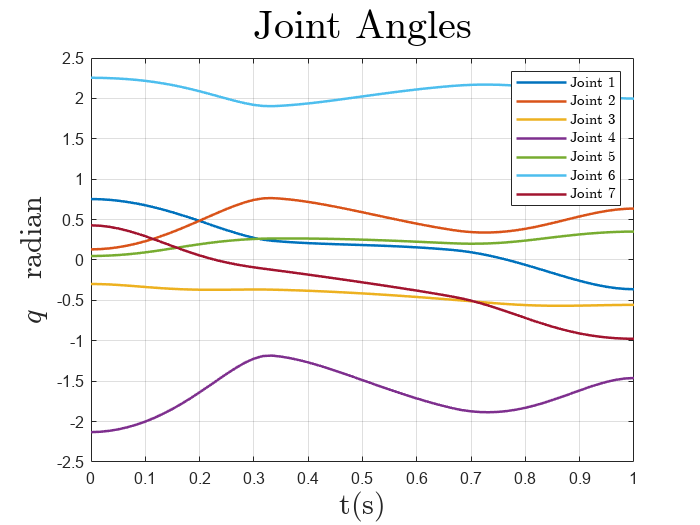


figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

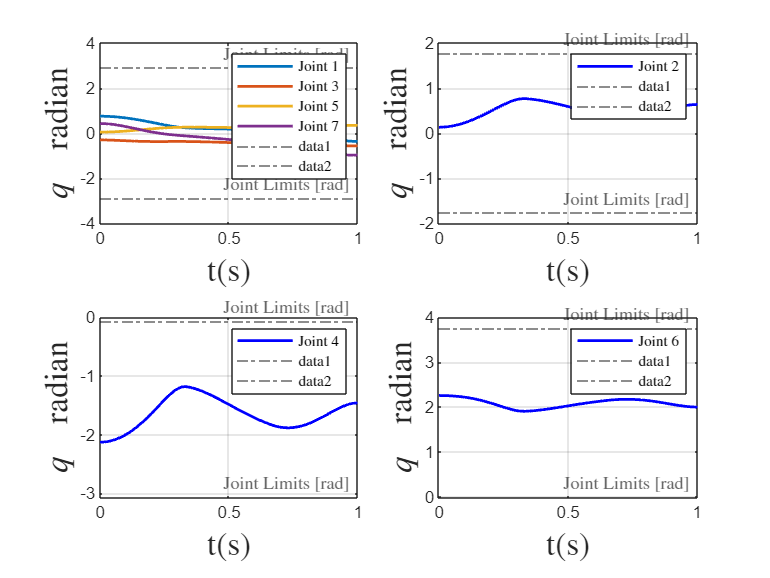

figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

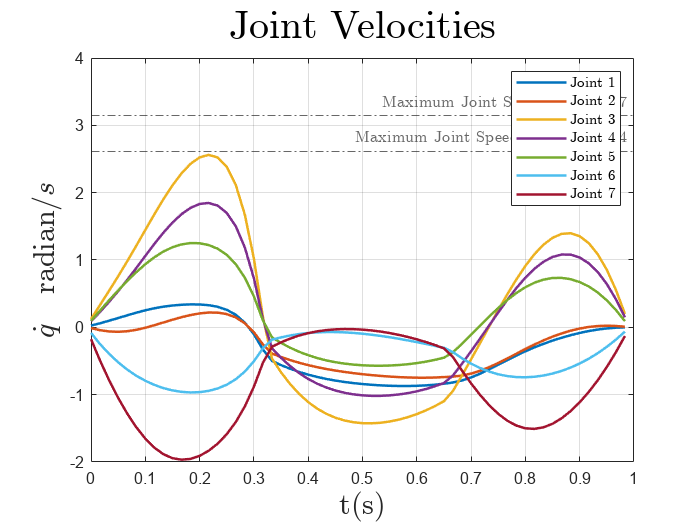


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

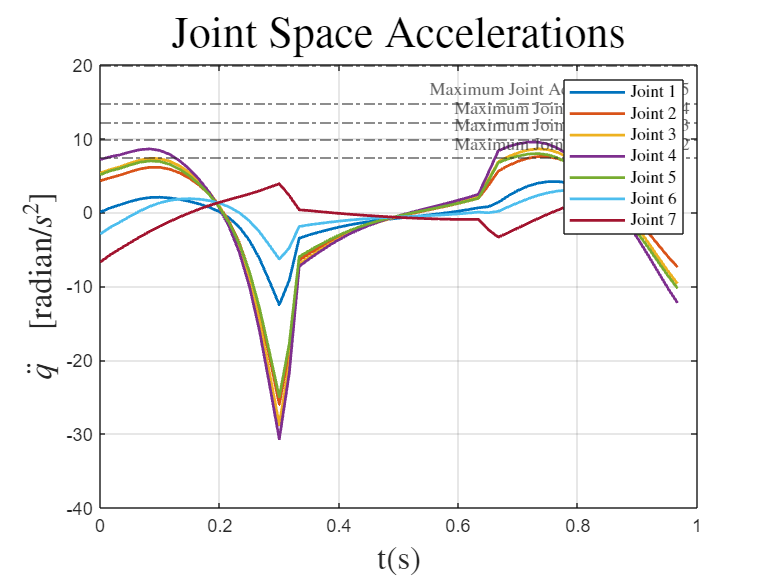


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

*Copyright 2021 The MathWorks, Inc.*